clearvars

# FEM Linear Analysis

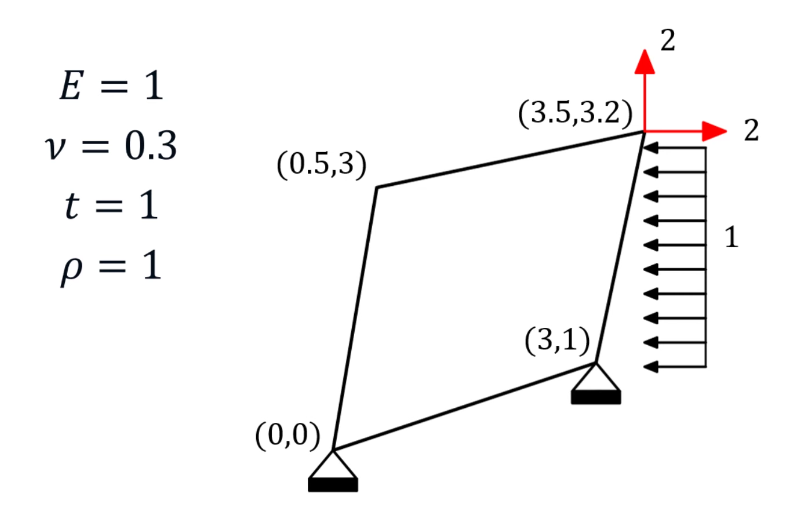

## Element Parameters

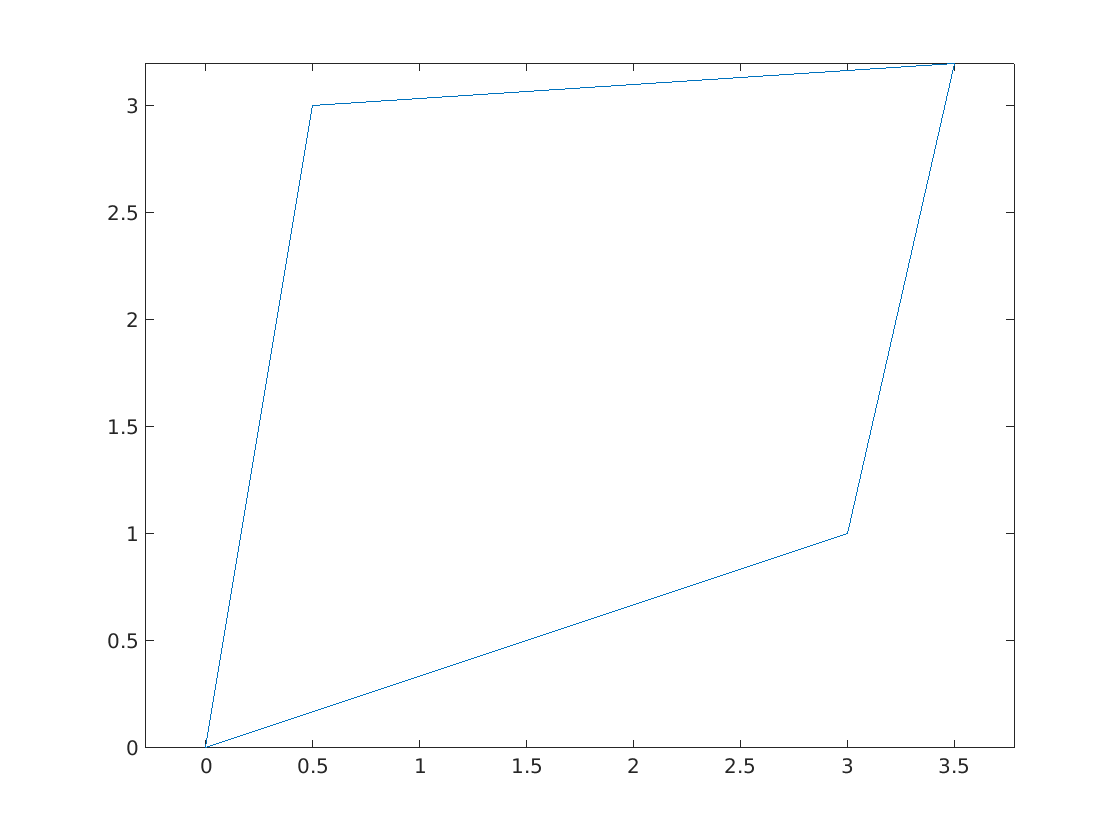

Coord = [0, 0; 3, 1; 3.5, 3.2; 0.5, 3];
t = 1;
E = 1;
v = 0.3;
p = 1;

plot([Coord(:,1); Coord(1,1)], [Coord(:,2); Coord(1,2)])
axis equal

## Loading Parameters

P = [0, 0, 0, 0, 2, 2, 0, 0]; % nodal forces
b = [0, -1]; % gravity
tn = [-1, 0]; % line load

## Constitutive Law

CStrain = (E/((1 + v)*(1 - 2*v))) ...
    * [
    1 - v, v, 0;
    v, 1 - v, 0;
    0, 0, (1 - 2*v)/2
    ];

% next Plane Stress
CStress = (E/(1 + v)) ...
    * [
    1/(1 - v), v/(1 - v), 0;
    v/(1 - v), 1/(1 - v), 0;
    0, 0, 0.5
    ];

C = CStress;

# Step 1: Stiffness Matrix

## Shape Functions

syms xi eta
% assume([xi eta], 'real');
N1 = (1 - xi)*(1 - eta)/4;
N2 = (1 + xi)*(1 - eta)/4;
N3 = (1 + xi)*(1 + eta)/4;
N4 = (1 - xi)*(1 + eta)/4;
Ni = [N1, N2, N3, N4];

## Coordinate Mapping

map = sym(zeros(2));
for n = 1:4
    map(n, 1) = Ni(n)*Coord(n, 1);
    map(n, 2) = Ni(n)*Coord(n, 2);
end

%    
%  (-1,1)    4--------------------3 (1,1) 
%            |                    |
%            |                    |
%            |          eta       |
%            |          |         |
%            |          --> xi    |
%            |                    |
%            |                    |
%            |                    |
%            |                    |
%  (-1,-1)   1--------------------2%   (1,-1) 
%
% newmap works korrekt
% newmap = subs(map, [xi, eta], [1, 1]);
% x = sum(newmap(:,1))
% y = sum(newmap(:,2))

x = sum(map(:,1))

$$x = \frac{7\,\left(\eta +1\right)\,\left(\xi +1\right)}{8}-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{8}-\frac{3\,\left(\eta -1\right)\,\left(\xi +1\right)}{4}$$

y = sum(map(:,2))

$$y = \frac{4\,\left(\eta +1\right)\,\left(\xi +1\right)}{5}-\frac{3\,\left(\eta +1\right)\,\left(\xi -1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{4}$$

CoordMap = [x, y]

$$CoordMap = \left(\begin{array}{cc} \frac{7\,\left(\eta +1\right)\,\left(\xi +1\right)}{8}-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{8}-\frac{3\,\left(\eta -1\right)\,\left(\xi +1\right)}{4} & \frac{4\,\left(\eta +1\right)\,\left(\xi +1\right)}{5}-\frac{3\,\left(\eta +1\right)\,\left(\xi -1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{4} \end{array}\right)$$

## N Matrix

Nn = sym(zeros(2, 8));
for n = 1:4
    Nn(1, 2*n - 1) = Ni(n);
    Nn(2, 2*n) = Ni(n);  
end

## Jacobian Matrix

NatCoord = [xi, eta];
J = sym(zeros(2));
for n = 1:2
    for m = 1:2
        J(n,m) = diff(CoordMap(n), NatCoord(m));
    end
end

Jinv = inv(J)';

## B Matrix

B1 = [
    1, 0, 0, 0;
    0, 0, 0, 1;
    0, 1, 1, 0
    ];

B2 = [
    Jinv(1,1), Jinv(1,2), 0, 0;
    Jinv(2,1), Jinv(2,2), 0, 0;
    0, 0, Jinv(1,1), Jinv(1,2);
    0, 0, Jinv(2,1), Jinv(2,2);
    ];

B3 = sym(zeros(4, 8));
for n = 1:4
    B3(1, 2*n - 1) = diff(Ni(n), xi);
    B3(3, 2*n) = diff(Ni(n), xi);
    B3(2, 2*n - 1) = diff(Ni(n), eta);
    B3(4, 2*n) = diff(Ni(n), eta);    
end

B = B1*B2*B3;

## Stiffness Matrix

IntFunc = ( B' * C * B )* det(J);

### Stiffnes Matrix (Actual Integration)

% ke = t * int(int(IntFunc, xi, -1, 1), eta, -1, 1); 
% double(ke)

high computation time!!!

### Stiffness Matrix (Full Gauss Integration)

xiset = [1/sqrt(3), -1/sqrt(3)];
etaset = [1/sqrt(3), -1/sqrt(3)];

kFull = sym(zeros(8));

for n = 1:2
    for m = 1:2
        kSmall = subs(IntFunc, [xi, eta], [xiset(n), etaset(m)]);
        kFull = kFull + kSmall;
    end
end

kFull = kFull * t;
double(kFull)

ans =     0.3226    0.1003   -0.2536    0.0001   -0.1012   -0.1436    0.0322    0.0433
    0.1003    0.3890    0.0275    0.0896   -0.1436   -0.1380    0.0158   -0.3405
   -0.2536    0.0275    0.7120   -0.3019   -0.0495    0.0318   -0.4089    0.2425
    0.0001    0.0896   -0.3019    0.7839    0.0593   -0.4332    0.2425   -0.4403
   -0.1012   -0.1436   -0.0495    0.0593    0.3907    0.0869   -0.2400   -0.0026
   -0.1436   -0.1380    0.0318   -0.4332    0.0869    0.4662    0.0249    0.1050
    0.0322    0.0158   -0.4089    0.2425   -0.2400    0.0249    0.6166   -0.2832
    0.0433   -0.3405    0.2425   -0.4403   -0.0026    0.1050   -0.2832    0.6758


### Stiffness Matrix (Reduced Gauss Integration)

kReduced = t * (2*2) * subs(IntFunc, [xi, eta], [0, 0]); 
double(kReduced)

ans =     0.2266    0.1190   -0.1223   -0.0256   -0.2266   -0.1190    0.1223    0.0256
    0.1190    0.2802    0.0018    0.2385   -0.1190   -0.2802   -0.0018   -0.2385
   -0.1223    0.0018    0.5321   -0.2667    0.1223   -0.0018   -0.5321    0.2667
   -0.0256    0.2385   -0.2667    0.5800    0.0256   -0.2385    0.2667   -0.5800
   -0.2266   -0.1190    0.1223    0.0256    0.2266    0.1190   -0.1223   -0.0256
   -0.1190   -0.2802   -0.0018   -0.2385    0.1190    0.2802    0.0018    0.2385
    0.1223   -0.0018   -0.5321    0.2667   -0.1223    0.0018    0.5321   -0.2667
    0.0256   -0.2385    0.2667   -0.5800   -0.0256    0.2385   -0.2667    0.5800


# Step 2: Nodal Forces Vector

## Nodal Loads due to Concentrated Loads

Fa = P;

## Nodal Loads due to Body Forces

pb = p*b;
pbFunc = (Nn' * pb') * det(J);

Fpb = sym(zeros(8, 1));

for n = 1:2
    for m = 1:2
        kSmall = subs(pbFunc, [xi, eta], [xiset(n), etaset(m)]);
        Fpb = Fpb + kSmall;
    end
end

% double(Fpb)

## Nodal Loads due to Traction Vectors

dl = subs(sqrt((diff(x, eta))^2 + (diff(y, eta))^2), xi, 1);
tnFunc = (Nn' * tn') * dl;
Ftn = t * subs(int(tnFunc, eta, -1, 1), xi, 1);

## Nodal Force Vector

Fn = Fa' + Fpb + Ftn;
double(Fn)

ans =          0
   -1.9583
   -1.1281
   -1.7583
    0.8719
    0.2083
         0
   -1.9917


# Step 3: Solve the System for Nodal Displacements

## Account for Boundary Conditions

Kglobal = kFull(5:8, 5:8);
Fglobal = Fn(5:8);

## Solve the linear System

NDisp = linsolve(Kglobal, Fglobal);
double(NDisp)

ans =     1.1899
    1.1120
   -1.2540
   -3.6410


## Nodal Displacement Vector

NodalDisp = zeros(8,1);
NodalDisp(5:8) = NDisp;

## Reaction Forces

NodalForces = kFull*NodalDisp;
ReactionForces = NodalForces - Fn;
double(ReactionForces)

ans =    -0.4780
    2.8540
    0.7341
    2.6460
   -0.0000
   -0.0000
    0.0000
   -0.0000


# Step 4: Displacement/Stress/Strain inside of the Element

## Displacement inside of the Element

ElementDisp = Nn*NodalDisp;

## Strain inside of the Element

Strain = B*NodalDisp;

Strain1 = subs(Strain, [xi, eta], [-1/sqrt(3), 1/sqrt(3)]);
Strain2 = subs(Strain, [xi, eta], [-1/sqrt(3), -1/sqrt(3)]);
Strain3 = subs(Strain, [xi, eta], [1/sqrt(3), 1/sqrt(3)]);
Strain4 = subs(Strain, [xi, eta], [1/sqrt(3), -1/sqrt(3)]);
Strain11 = [Strain1(1), Strain2(1), Strain3(1), Strain4(1)];
Strain22 = [Strain1(2), Strain2(2), Strain3(2), Strain4(2)];
Strain12 = [Strain1(3), Strain2(3), Strain3(3), Strain4(3)];

double(Strain11')

ans =     0.6895
    0.2569
    0.6237
    0.0992


double(Strain22')

ans =    -1.1776
   -1.0414
   -0.2241
   -0.0268


double(Strain12')

ans =     1.0121
    0.3174
    1.4297
    0.6055


## Stresses inside of the Element

Stress = C*Strain;

Stress1 = subs(Stress, [xi, eta], [-1/sqrt(3), 1/sqrt(3)]);
Stress2 = subs(Stress, [xi, eta], [-1/sqrt(3), -1/sqrt(3)]);
Stress3 = subs(Stress, [xi, eta], [1/sqrt(3), 1/sqrt(3)]);
Stress4 = subs(Stress, [xi, eta], [1/sqrt(3), -1/sqrt(3)]);
Stress11 = [Stress1(1), Stress2(1), Stress3(1), Stress4(1)];
Stress22 = [Stress1(2), Stress2(2), Stress3(2), Stress4(2)];
Stress12 = [Stress1(3), Stress2(3), Stress3(3), Stress4(3)];

double(Stress11')

ans =     0.3695
   -0.0610
    0.6115
    0.1002


double(Stress22')

ans =    -1.0668
   -1.0597
   -0.0407
    0.0032


double(Stress12')

ans =     0.3893
    0.1221
    0.5499
    0.2329
